clear; clc;

% CONFIGURA AQUÍ TUS RUTAS
carpeta = 'C:\Users\56931\Desktop\Proyecto\Data_final';
ruta_guardado = 'C:\Users\56931\Desktop\Proyecto\Resultados';

archivos = dir(fullfile(carpeta, '*.xls'));
n = length(archivos);

% VARIABLES DE SALIDA
nombres = strings(n,1);
Wb = NaN(n,1); H = NaN(n,1); Vol = NaN(n,1); Slope = NaN(n,1);
Wcr = NaN(n,1);
H_Wb = NaN(n,1); Wcr_Wb = NaN(n,1);
Ellipticity = NaN(n,1); Irregularity = NaN(n,1);
Orientation = NaN(n,1);
Basal_Ellipticity = NaN(n,1); Crater_Ellipticity = NaN(n,1);
Basal_Azimuth = NaN(n,1); Crater_Azimuth = NaN(n,1);
VolErodado = NaN(n,1);
Indice_Erosion = NaN(n,1);


for i = 1:n
    archivo = fullfile(carpeta, archivos(i).name);
    nombres(i) = archivos(i).name;

    % ==== SIZE PARAMETERS ====
    sizeData = readcell(archivo, 'Sheet', 'Size_Parameters');
    for j = 1:size(sizeData,1)
        if ischar(sizeData{j,1}) || isstring(sizeData{j,1})
            txt = strtrim(sizeData{j,1});
            switch txt
                case 'Basal Width (m):'
                    Wb(i) = sizeData{j,2};
                case 'Maximum Height (m):'
                    H(i) = sizeData{j,2};
                case 'Maximum Volume (m3):'
                    Vol(i) = sizeData{j,2};               
                case 'Basal Ellipse Axis Ellipticity:'
                    Basal_Ellipticity(i) = sizeData{j,2};  
                case 'Minimum Eroded Volume (m3):'
                    VolErodado(i) = sizeData{j,2};
            end
        end
    end

    % ==== SLOPE PARAMETERS ====
    slopeData = readcell(archivo, 'Sheet', 'Slope_Parameters');
    for j = 1:size(slopeData,1)
        if ischar(slopeData{j,1}) || isstring(slopeData{j,1})
            if strcmp(strtrim(slopeData{j,1}), 'Flank Mean Slope (deg.):')
                Slope(i) = slopeData{j,2};
            end
        end
    end

    % ==== SHAPE PARAMETERS ====
    shapeData = readcell(archivo, 'Sheet', 'Shape_Parameters');
    for j = 1:size(shapeData,1)
        if ischar(shapeData{j,1}) || isstring(shapeData{j,1})
            switch strtrim(shapeData{j,1})
                case 'Mean Contour Maximum Diameter Irregularity Index:'
                    Irregularity(i) = shapeData{j,2};
            end
        end
    end

    % ==== ORIENTATION PARAMETERS ====
    orientData = readcell(archivo, 'Sheet', 'Orientation_Parameters');
    for j = 1:size(orientData,1)
        if ischar(orientData{j,1}) || isstring(orientData{j,1})
            switch strtrim(orientData{j,1})
                case 'Basal Ellipse Orientation (deg.):'
                    Basal_Azimuth(i) = orientData{j,2};              
            end
        end
    end
% ==== CRATER_1_PARAMETERS ====
% ==== CRATER_1_PARAMETERS ====
try
    craterData = readcell(archivo, 'Sheet', 'Crater_1_Parameters');
    for j = 1:size(craterData,1)
        if ischar(craterData{j,1}) || isstring(craterData{j,1})
            txt = strtrim(craterData{j,1});
            switch txt
                case 'Crater Width (m):'
                    Wcr(i) = craterData{j,2};
                case 'Crater Ellipse Major Axis (m):'
                    Crater_Major(i) = craterData{j,2};
                case 'Crater Ellipse Minor Axis (m):'
                    Crater_Minor(i) = craterData{j,2};
                case 'Crater Ellipse Azimuth (deg.):'
                    Crater_Azimuth(i) = craterData{j,2};
                case 'Crater Best-Fitting Ellipse Axis Ellipticity:'
                    Crater_Ellipticity(i) = craterData{j,2};
            end
        end
    end
catch
    Wcr(i) = NaN;
    Crater_Major(i) = NaN;
    Crater_Minor(i) = NaN;
    Crater_Ellipticity(i) = NaN;
    Crater_Azimuth(i) = NaN;
end


    % ==== CÁLCULOS DERIVADOS ====
    if ~isnan(H(i)) && ~isnan(Wb(i)) && Wb(i) ~= 0
        H_Wb(i) = H(i) / Wb(i);
    end
    if ~isnan(Wcr(i)) && ~isnan(Wb(i)) && Wb(i) ~= 0
        Wcr_Wb(i) = Wcr(i) / Wb(i);
    end
        if ~isnan(VolErodado(i)) && ~isnan(Vol(i)) && Vol(i) ~= 0
        Indice_Erosion(i) = VolErodado(i) / Vol(i);
    end

end

% === GUARDAR TABLA COMPLETA ===
tabla = table(nombres, Wb, H, Vol, VolErodado, Indice_Erosion, Slope, ...
              Wcr, H_Wb, Wcr_Wb, ...
              Basal_Ellipticity, Crater_Ellipticity, ...
              Irregularity, Basal_Azimuth, Crater_Azimuth);

disp(tabla);

                  nombres                    Wb        H          Vol        VolErodado    Indice_Erosion    Slope      Wcr        H_Wb      Wcr_Wb     Basal_Ellipticity    Crater_Ellipticity    Irregularity    Basal_Azimuth    Crater_Azimuth
    ___________________________________    ______    ______    __________    __________    ______________    ______    ______    ________    _______    _________________    __________________    ____________    _____________    ______________

   

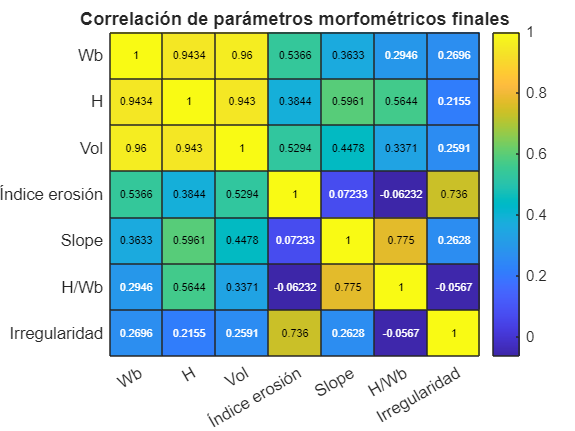


nombre_salida = fullfile(ruta_guardado, 'parametros_morfometricos_final1.xlsx');
writetable(tabla, nombre_salida);

% === MATRIZ DE CORRELACIÓN ===
parametros_num = [Wb, H, Vol, Indice_Erosion, Slope, H_Wb, ...
                  Irregularity];

etiquetas = {'Wb','H','Vol','Índice erosión','Slope','H/Wb', ...
             'Irregularidad'};


% Filtrar columnas con más de un dato válido
valores_validos = sum(~isnan(parametros_num)) > 1;
parametros_validos = parametros_num(:, valores_validos);
etiquetas_validas = etiquetas(valores_validos);

R = corrcoef(parametros_validos, 'Rows', 'pairwise');

figure;
heatmap(etiquetas_validas, etiquetas_validas, R, ...
        'Colormap', parula, 'ColorbarVisible','on');
title('Correlación de parámetros morfométricos finales');

saveas(gcf, fullfile(ruta_guardado, 'correlaciones_morfometria_final1.png'));
saveas(gcf, fullfile(ruta_guardado, 'correlaciones_morfometria_final1.pdf'));